% Done!
clear; close all;
% load letterA.mat;
% X = A;
load letterX.mat

## Original image

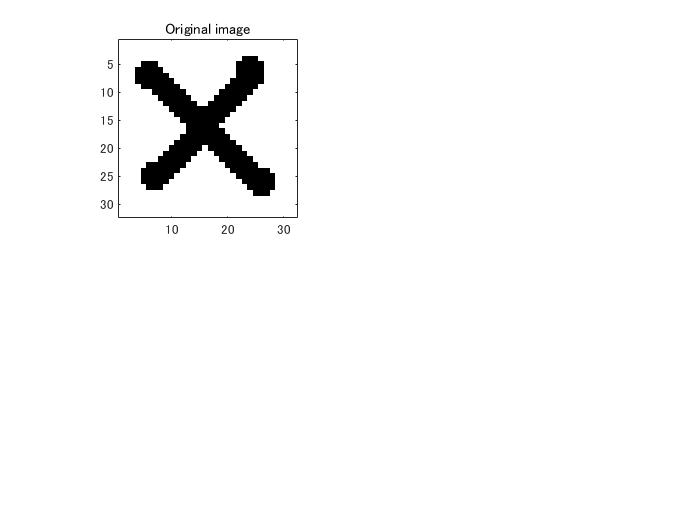

img = double(X);
img = sign(img-mean(img(:)));

figure;
subplot(2,2,1);
imagesc(img);
title('Original image');
axis image;
colormap gray;

## Noisy image

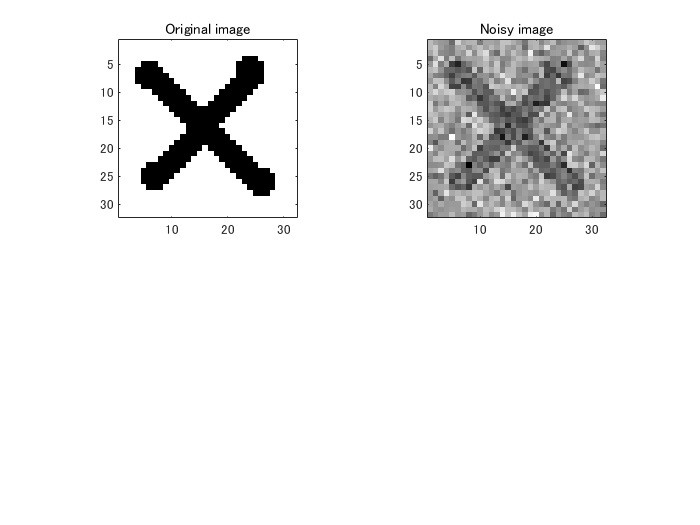

sigma = 1; % noise level
x = img + sigma*randn(size(img)); % noisy signal
subplot(2,2,2);
imagesc(x);
title('Noisy image');
axis image;
colormap gray;

## Construct MRF data

epoch = 20;
J = 1;   % ising parameter
[A,nodePot,edgePot] = mrfIsGa(x,sigma,J);

## Mean Field

[nodeBel0,edgeBel0,lnZ0] = mrfMf(A,nodePot,edgePot,epoch);

L0 = mrfGibbs(A,nodePot,edgePot,nodeBel0);
L1 = mrfBethe(A,nodePot,edgePot,nodeBel0,edgeBel0);
maxdiff(L0,lnZ0(end))

ans = 0

maxdiff(L0,L1)

ans = 0

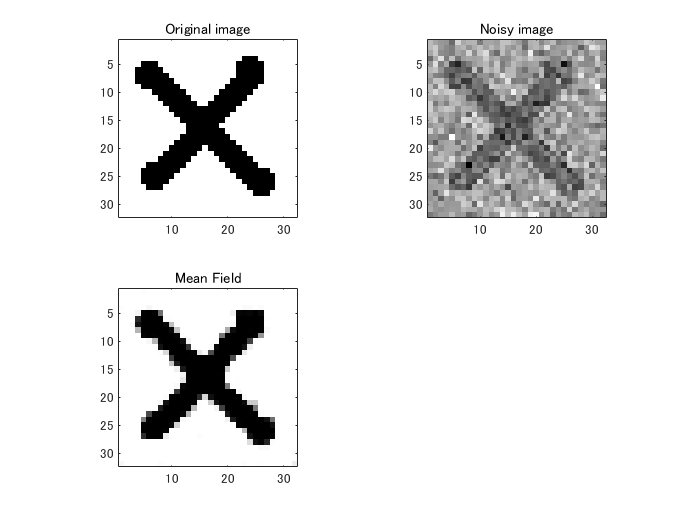


subplot(2,2,3);
imagesc(reshape(nodeBel0(1,:),size(img)));
title('Mean Field');
axis image;
colormap gray;

## Belief Propagation

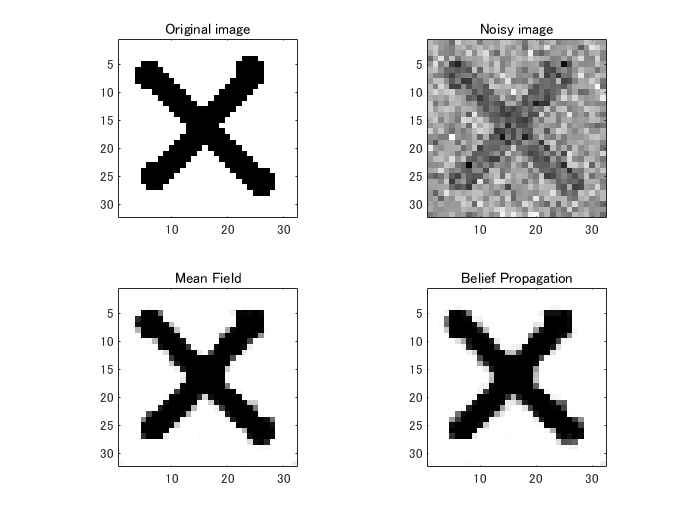

[nodeBel1,edgeBel1,lnZ1] = mrfBp(A,nodePot,edgePot,epoch);

subplot(2,2,4);
imagesc(reshape(nodeBel1(1,:),size(img)));
title('Belief Propagation');
axis image;
colormap gray;

## Energy comparation

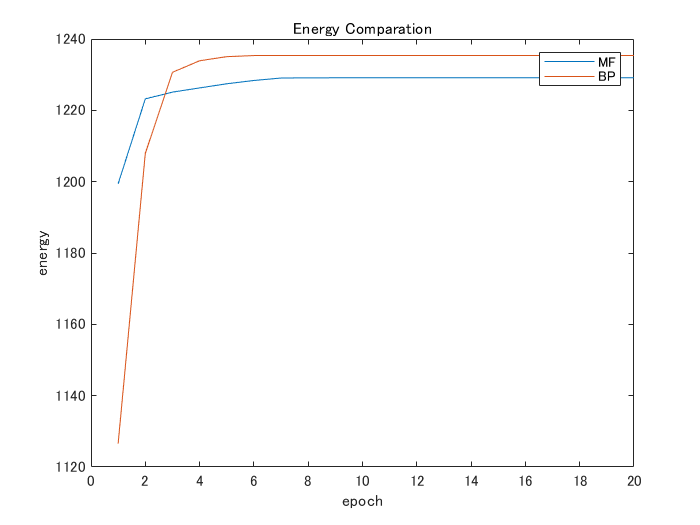

figure
epochs = 1:epoch;
plot( epochs,lnZ0,'-', ...
      epochs,lnZ1,'-');
xlabel('epoch');       %  add axis labels and plot title
ylabel('energy');
title('Energy Comparation');
legend('MF','BP');